# Modeling and Optimizing a Battery Charging Profile

In this project, you will use MATLAB to model a battery charging profile. You will fit real lithium‑ion battery data in MATLAB, compute energy transfer through numerical integration, and analyze key performance characteristics such as charge‑rate behavior and efficiency losses.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Given data for a lithium-ion battery charging profile, use MATLAB to fit the equation for voltage provided in the Project Description.

- Plot the following curves: voltage vs. time, current vs. time, and power vs. time.

- Use integration to compute the total energy delivered to the battery (area under power-time curve).

- Analyze the rate of voltage change at different intervals (calculate derivatives), compute the time to reach 80% and 100% charge, and compute the energy lost due to resistance.

## Break Down the Problem

In the space below, define the problem statement:

List the requirements, constraints, and success criteria for the project:

What is your proposed solution?

List the steps you will need to take to achieve your proposed solution:

What challenges do you face in the process of achieving the solution?

## Task 1: Fit the voltage equation to a lithium-ion battery profile

Given real time-series voltage data for a lithium-ion battery, use MATLAB Curve Fitting Toolbox to fit the equation $V\left(t\right)=V_{\max } \left(1-e^{-\frac{t}{\mathrm{RC}}} \right)$ and model the battery charging profile as a simple RC-circuit analog.

Load MathWorks example lithium-ion batteries data by following the steps [here](https://www.mathworks.com/help/predmaint/ug/data-analysis-and-feature-extraction-for-battery-raw-cycling-data.html). The page also includes information about the dataset, how the data was recorded, and the battery's maximum voltage.

**Note**: The battery from this example dataset has been cycled to failure (charged and discharged repeatedly). For this project, you may choose to use data from a single cycle and focus only on the period of time within a cycle that the battery is being charged. The battery is fully charged at 3.6V. This example battery uses a dynamic fast charging profile, but for this project, you will attempt to model the charging profile using a simple exponential capacitor charging equation.

Then, follow the workflow outlined in the [documentation](https://www.mathworks.com/help/curvefit/fit.html) to fit the voltage equation to your selected data. Plot the data and fitted curve in the same figure and, finally, print the goodness-of-fit statistics.

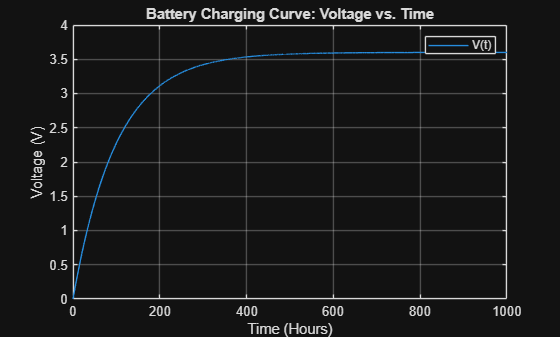

Vmax = 3.6;    %[Volt]
R = 10;        %[Ohm]
C = 10;        %[farad]
t = linspace(0,1000, 10000);            %[Second]

V_t = Vmax * (1 - exp(-t / (R * C)));

figure;
simple_charge_graph = plot(t,V_t,"DisplayName","V(t)");
legend
grid on
xlabel("Time (Hours)")
ylabel("Voltage (V)")
title("Battery Charging Curve: Voltage vs. Time")


dataFile = matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile)
load("singleCellLifeTimeData.mat")

bParser = batteryTestDataParser(data);
bParser.CurrentVariable = 'Current';
bParser.VoltageVariable= "Voltage";
bParser.TimeVariable = "DateTime";
bParser.CycleIndexVariable = 'Cycle_Index';
bParser.StepIndexVariable = 'Step_Index';  

segmentedRawDataTable = segmentData(bParser);
head(segmentedRawDataTable,5)

    Data_Point    Test_Time          DateTime          Step_Time    Step_Index    Cycle_Index    Current    Voltage    Charge_Capacity    Discharge_Capacity    Charge_Energy    Discharge_Energy       dV/dt       Internal_Resistance    Temperature    CyclingModes    CyclingPhases    IsValid
    __________    _________    ____________________    _________    __________    ___________    _______    _______    _______________    __________________    _____________    ________________    <s

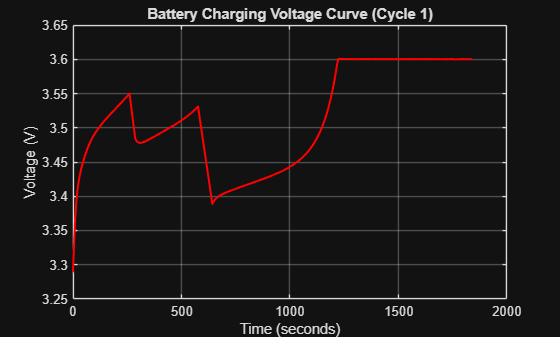


chargingData = segmentedRawDataTable(segmentedRawDataTable.Cycle_Index == 1 & ...
    segmentedRawDataTable.CyclingPhases == "Charge" & ...
    segmentedRawDataTable.IsValid, :);
chargingData.TimeInSeconds = seconds(chargingData.DateTime - chargingData.DateTime(1));

figure;
plot(chargingData.TimeInSeconds, chargingData.Voltage, '-r', 'LineWidth', 1.5);

xlabel('Time (seconds)');
ylabel('Voltage (V)');
title('Battery Charging Voltage Curve (Cycle 1)');
grid on;

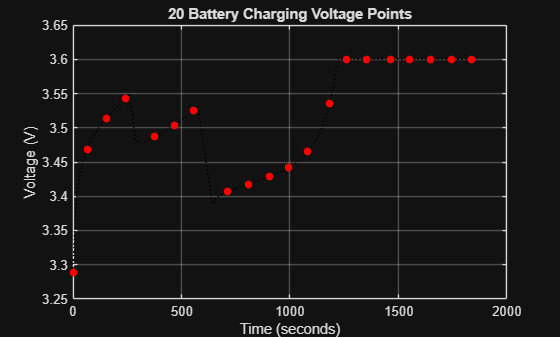


totalPoints = height(chargingData);
evenIndices = round(linspace(1, totalPoints, 20));

% 4. Extract those 20 specific points
evenTime = chargingData.TimeInSeconds(evenIndices);
evenVoltage = chargingData.Voltage(evenIndices);

% 5. Create the plot
figure;
% Plot a faint line in the background so you can see the trend, 
% then overlay the 20 distinct points as red circles
plot(chargingData.TimeInSeconds, chargingData.Voltage, ':k', 'LineWidth', 1); % Dotted background line
hold on;
plot(evenTime, evenVoltage, 'or', 'MarkerSize', 5, 'MarkerFaceColor', 'r'); % 20 Evenly-spaced points
hold off;

xlabel('Time (seconds)');
ylabel('Voltage (V)');
title('20 Battery Charging Voltage Points');
grid on;

## Task 2: Plot the electrical terms that express how energy moves in a circuit

To visualize the battery's charging policy, write code to visualize the current, voltage, and power measurements for one charging cycle. Present the visualization as one figure with three subplots, one each for:

- Voltage vs. time

- Current vs. time

- Power vs. time

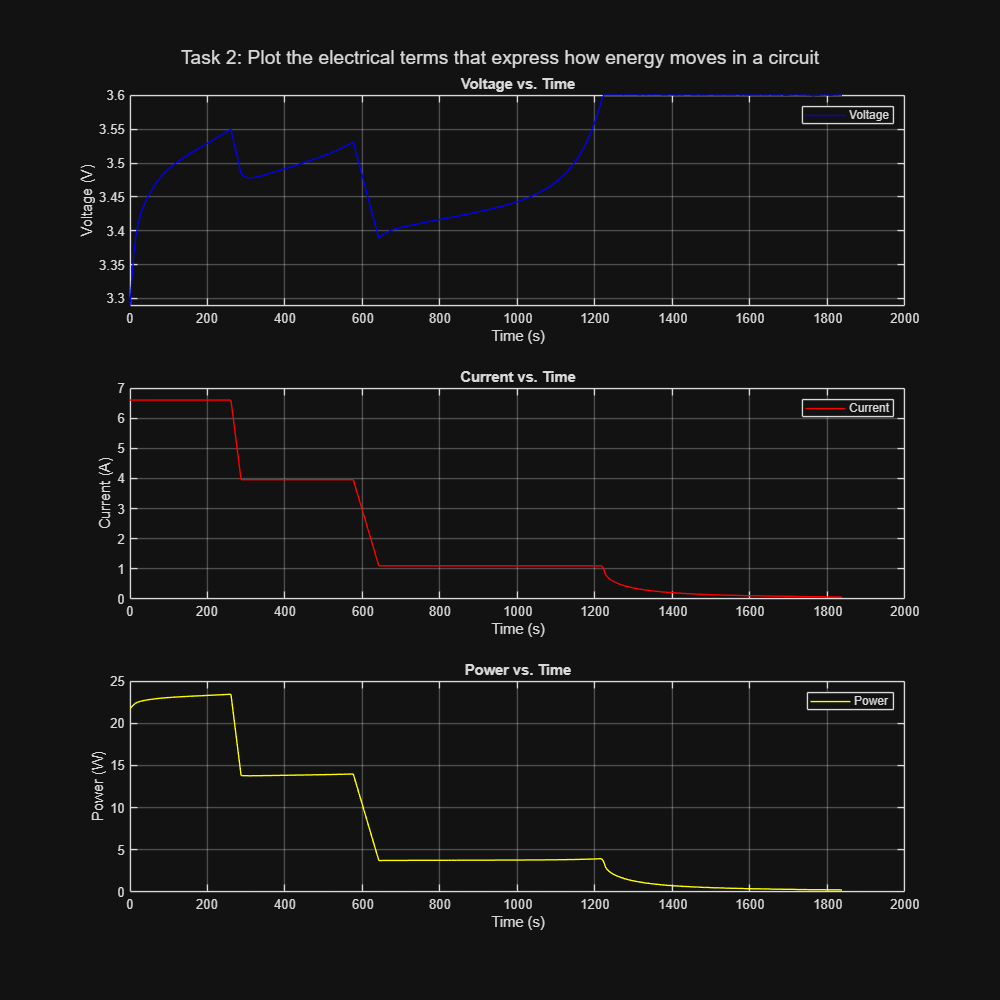

% Set current, voltage, and time variables to pull from the filtered chargingData
I = chargingData.Current;
V = chargingData.Voltage;
t = chargingData.TimeInSeconds;

% Calculate power by multiplying current and voltage
P = I .* V;

% Create a figure handle
figure('Name', 'Task 2', 'Position', [0, 0, 1000, 1000]);

% STEP 1: Initialize the first subplot. Plot voltage vs. time.
subplot(3, 1, 1)
plot(t, V, 'b', 'DisplayName', 'Voltage')
title('Voltage vs. Time')
xlabel('Time (s)')
ylabel('Voltage (V)')
legend
grid on

% STEP 2: Use a second subplot to plot current vs. time.
subplot(3, 1, 2)
plot(t, I, 'r', 'DisplayName', 'Current')
title('Current vs. Time')
xlabel('Time (s)')
ylabel('Current (A)')
legend
grid on

% STEP 3: Use a third subplot to plot power vs time.
subplot(3, 1, 3)
plot(t, P, 'y', 'DisplayName', 'Power')
title('Power vs. Time')
xlabel('Time (s)')
ylabel('Power (W)')
legend
grid on

% Add a main title for the entire figure
sgtitle('Task 2: Plot the electrical terms that express how energy moves in a circuit')

## Task 3: Compute analytical results

To get started on using MATLAB for numerical integration and differentiation, start with this [doc page](https://www.mathworks.com/help/matlab/numerical-integration-and-differentiation.html?s_tid=CRUX_lftnav).

- Conduct a rate-of-change analysis by computing the derivative at key intervals in the voltage data

- Compute the time required to reach 80% and 100% charge

- Compute the total energy delivered to the battery by using integration to calculate the area under the power-time curve.

- Estimate the resistive energy loss

- Save the results to a summary table.

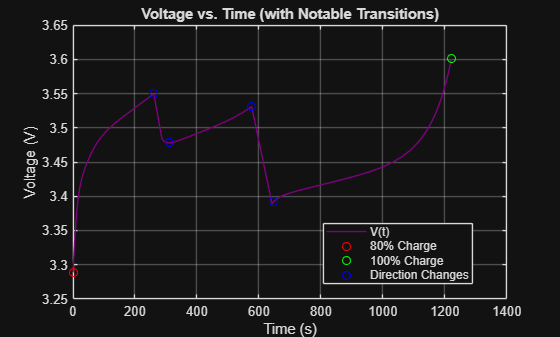

% Insert your code in the spaces below (or make use of helper functions and indicate where
% they can be found). Ensure your code is well-documented.

% STEP 1: Compute the rate of voltage change at different key time
% intervals. This helps you mathematically characterize the battery's
% charging profile and is more reliable than simply eyeballing the voltage
% vs. time plot. 
% Optional: plot the points of notable transitions in charging dynamics in
% the voltage vs. time plot generated above
% Hint: explore using the gradient function


% Identify time interval of 100% charge
vMax  = 3.6;
i100 = find(V >= vMax, 1);
t100 = t(i100);
v100 = V(i100);

% Compute the rate of voltage change and set maximum voltage
tPlot = t(1:i100);
vPlot = V(1:i100);
dVdt  = gradient(vPlot, tPlot);

% Identify time interval of 80% charge
v80   = 0.80 * vMax;
i80 = find(vPlot >= v80, 1);

t80 = tPlot(i80);
v80 = vPlot(i80); % Actual voltage (2.88v) is not on the interval

% Identify time interval of direction changes
iDC = find(diff(sign(dVdt)) ~= 0) + 1;
tDC = tPlot(iDC);
vDC = vPlot(iDC);

% Plot notable transitions
figure('Name', 'Task 3.1');
plot(tPlot, vPlot, 'Color', [0.5, 0, 0.5]);
hold on;

plot(t80, v80, 'ro');
plot(t100, v100, 'go');
plot(tDC, vDC, 'bo');

title('Voltage vs. Time (with Notable Transitions)');
xlabel('Time (s)');
ylabel('Voltage (V)');
legend('V(t)', '80% Charge', '100% Charge', ...
       'Direction Changes', 'Location', 'best');
grid on;
box on;
hold off;



% STEP 2: Compute the time required to reach 80% charge and 100% charge

% STEP 3: Use integration to calculate the area under the power-time curve.
% This represents the total energy delivered to the battery during charging.
% Hint: explore using the trapz function

% STEP 4: Estimate the resistive energy loss. 
% Hint: use Joule's heating formula (P = I^2 * R) to estimate power loss in
% watts. The energy loss is given as E = P * t, where t is time in seconds
% and energy is in joules.

% STEP 5: Save results to a summary table. Display the table.



## Interpretation of Results

Summarize your findings by interpreting their physical/engineering meaning (for example, why would engineers want to compute the analytical results in Task 3?):

What are some limitations of your work?

What are practical next steps?